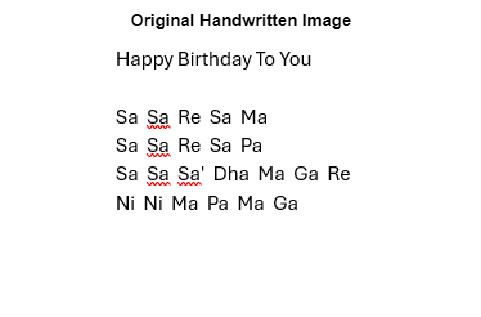

close all;clear all;
% Handwritten OCR Example in MATLAB

I = imread("C:\Users\keert\OneDrive\Desktop\happybday.png");
imshow(I); title('Original Handwritten Image');


grayImage = rgb2gray(I);
grayImage = imadjust(grayImage); % Enhance contrast

bw = imbinarize(grayImage, 'adaptive', 'ForegroundPolarity', 'dark', 'Sensitivity', 0.4);
bw = bwareaopen(bw, 30); % Remove small noise

se = strel('line',2,0);
bw = imclose(bw, se); % Connect strokes

results = ocr(bw, 'TextLayout','Block');

disp('Recognized Handwritten Text:');

Recognized Handwritten Text:


disp(results.Text);


function [audio, texx] = to_generate_Ar_Av(sa_freq, duration, notes)
    % Swara to Frequency Ratio Map
    ratios = struct( ...
        'S', 1.0, ...
        'R', 9/8, ...   % R2
        'G', 5/4, ...   % G2
        'M', 4/3, ...   % Ma
        'P', 3/2, ...   % Pa
        'D', 27/16, ... % D2
        'N', 9/5, ...   % Ni2
        'Sa', 2.0);     % High Sa

    % Sampling rate
    sr = 22050;

    % Initialize
    audio = [];
    texx = {};

    % Generate waveform for each note
    for i = 1:length(notes)
        note = strtrim(string(notes(i)));

        if isfield(ratios, note)
            texx{end+1} = note; %#ok<AGROW>
            f = sa_freq * ratios.(note);
            t = linspace(0, duration, round(sr*duration));
            wave = 0.5 * sin(2*pi*f*t);
            audio = [audio, wave]; %#ok<AGROW>
        end
    end
end


sa_freq = 261.63;       % Base frequency (Sa)
duration = 0.8;         % Duraton per note

[audio, texx] = to_generate_Ar_Av(sa_freq, duration, results.Text);

sound(audio, 22050);    % Play the sound
audiowrite('swara_output.wav', audio, 22050);

Error using audiowrite
The value of 'y' is invalid. Expected input to be nonempty.

Error in audiowrite>parseInputs (line 305)
parse(p,filename, y, Fs, pvpairs{:});

Error in audiowrite (line 137)
props = parseInputs(filename, y, Fs, varargin);

% Handwritten OCR Example in MATLAB

I = imread("C:\Users\keert\OneDrive\Desktop\twinkle_twinkle.jpg");
imshow(I); title('Original Handwritten Image');

grayImage = rgb2gray(I);
grayImage = imadjust(grayImage); % Enhance contrast

bw = imbinarize(grayImage, 'adaptive', 'ForegroundPolarity', 'dark', 'Sensitivity', 0.4);
bw = bwareaopen(bw, 30); % Remove small noise

se = strel('line',2,0);
bw = imclose(bw, se); % Connect strokes

results = ocr(bw, 'TextLayout','Block');
disp('Recognized Handwritten Text:');
disp(results.Text);


sa_freq = 261.63;       % Base frequency (Sa)
duration = 0.8;         % Duraton per note

[audio, texx] = to_generate_Ar_Av(sa_freq, duration, results.Text);

sound(audio, 22050);    % Play the sound
audiowrite('swara_output.wav', audio, 22050);

Function 'to_generate_Ar_Av' has already been declared within this scope.